n1=-5:5;%显然，用逻辑式是比较高明的方法
x1=(n1-0)==0;%逻辑判断，自动循环，满条件置1。
stem(n1,x1);
%作用是绘制以n1为横坐标，x1为纵坐标的离散杆图
title('单位脉冲序列');
%绘图标题
axis([-5,5,0,1]);
%横坐标从-5到5，纵坐标从0到1

clear;
n1=-5:5;x1=(n1-0)>=0;%用逻辑式是比较高明的方法
stem(n1,x1);
title('阶跃序列');
axis([-5,5,0,1.1]);

clear;
n=0:40;
x1=3*cos(0.1*pi*n+pi/3);
x2=2*sin(0.2*pi*n);
subplot(2,1,1);
stem(n,x1);title('余弦序列');
subplot(2,1,2);
stem(n,x2);title('正弦序列');

clear;
n1=0:40;
x1=exp((0.1+(pi/6)*i)*n1);
subplot(2,1,1);
stem(n1,real(x1));title('复指数序列');
ylabel('实部');
subplot(2,1,2);
stem(n1,imag(x1));
ylabel('虚部');

clc;clear all;
n=-3:10;k0=3;k1=-3;
x=cos(2*pi*n/10);%原信号x(n)
x1=cos(2*pi*(n-k0)/10);%x(n-2)
x2=cos(2*pi*(n-k1)/10);%x(n+2)
subplot(3,1,1),stem(n,x,'filled','k');
ylabel('x(n)');
subplot(3,1,2),stem(n,x1,'filled','k');
ylabel('x(n-3)');
subplot(3,1,3),stem(n,x2,'filled','k');
ylabel('x(n+3)');

clc;clear all;
x1=[0,1,2,3,4,3,2,1,0];ns1=-2;
%给定x1及ns1
x2=[2,2,0,0,0,-2,-21];ns2=2;
%给定x2及ns2
nf1=ns1+length(x1)-1;nf2=ns2+length(x2)-1;
ny=min(ns1,ns2):max(nf1,nf2);
%y(n)的时间变量
xa1=zeros(1,length(ny));xa2=xa1;%延拓序列初始化
xa1(find((ny>=ns1)&(ny<=nf1)==1))=x1;%给xa1赋值x1
xa2(find((ny>=ns2)&(ny<=nf2)==1))=x2;%给xa2赋值x2
ya=xa1 +xa2
%序列相加
yp=xa1.*xa2
%序列相乘


xn=sin(0.4*(1:15))';hn=0.9.^(1:20)';
M=length(xn);N=length(hn);
nx=1:M;nh=1:N;%循环卷积区间长度
L=M+N-1;
L=pow2(nextpow2(M+N-1));%取L为大于等于且最接近N+M-1)的2的正次幂
tic,
%快速卷积计时开始
Xk=fft(xn,L);Hk=fft(hn,L);%L FFT
Yk=Xk.*Hk;
%频域相乘得Yk)
yn=ifft(Yk,L);
%L点FFT得到卷积结果
toc%快速卷积计时结束
plot([1:M],xn,[1:N],hn,[1:L],yn);
grid on;

tic,
yn=conv(xn,hn);%直接conv计算卷积
toc

n = 0:20; % 定义数列范围

for i = 1:length(n)
    if n(i) >= 0 && n(i) <= 3
        s(i) = n(i);
    elseif n(i) > 3 && n(i) <= 8
        s(i) = 8 - n(i);
    else
        s(i) = 0;
    end
end

stem(n, s) % 绘制数列图像，使用stem函数可以绘制离散的数据点
xlabel('n') % x轴标签
ylabel('s[n]') % y轴标签
title('分段数列') % 绘图标题
Xc=fft(s,8);
stem(1:8, Xc)

1)Butterworth数字滤波器设计(由模拟双线性转换为数字滤波器)

FS=1000;
Fl=20;Fh=50;%通带、阻带截止须率
Rp=1;Rs=15;
wp1=Fl*2*pi/FS;%求通带数字频率
ws1=Fh*2*pi/FS;%求阻带数字频率
OmegaP=2*FS*tan(wp1/2);%频率预畸
OmegaS=2*FS*tan(ws1/2);%频率预畸
%选择滤波器的最小阶数
[n,Wn]=buttord(OmegaP,OmegaS,Rp,Rs,'s');%此处是代入经预畸变后获得的归一化模拟频率参数
[bt,at]=butter(n,Wn,'s');%设计一个n阶的巴特沃思模拟滤波器
[bz1,az1]=bilinear(bt,at,FS);%双线性变换为数字滤波器
[H,W]=freqz(bz1,az1);%求解数字滤波器的频率响应
plot(W*FS/(2*pi),abs(H));grid;
xlabel('频率/Hz');ylabel('幅值');

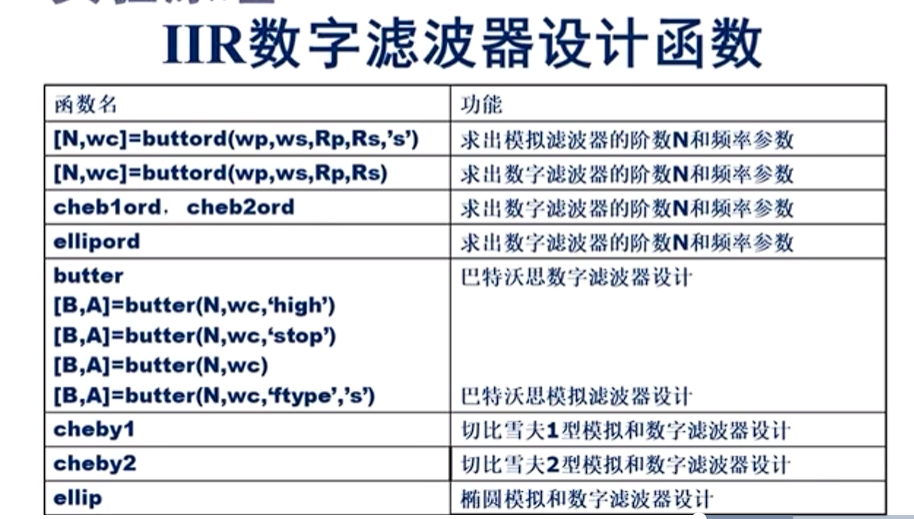

FS=1000;
Rp=1;Rs=15;
OmegaP=0.2*pi/pi;
OmegaS=0.35*pi/pi;
%选择滤波器的最小阶数
[n,Wn]=buttord(OmegaP,OmegaS,Rp,Rs);
[bt,at]=butter(n,Wn);%设计一个n阶的巴特沃思模拟滤波器
[H,W]=freqz(bt,at);%求解数字滤波器的频率响应
plot(W*FS/(2*pi),abs(H));grid;
xlabel('频率/Hz');ylabel('幅值');

模拟滤波器双线性变换法

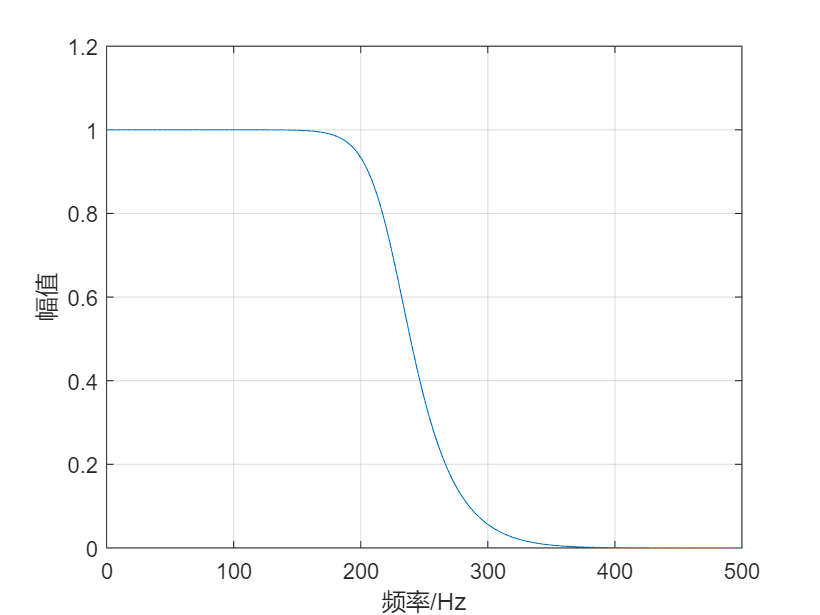

FS=1000;
Fl=200;Fh=300;%通带、阻带截止须率
Rp=1;Rs=25;
wp1=Fl*2*pi/FS;%求通带数字频率
ws1=Fh*2*pi/FS;%求阻带数字频率
OmegaP=2*FS*tan(wp1/2);%频率预畸
OmegaS=2*FS*tan(ws1/2);%频率预畸
%选择滤波器的最小阶数
[n,Wn]=buttord(OmegaP,OmegaS,Rp,Rs,'s');%此处是代入经预畸变后获得的归一化模拟频率参数
[bt,at]=butter(n,Wn,'s');%设计一个n阶的巴特沃思模拟滤波器
[bz,az]=bilinear(bt,at,FS);%双线性变换为数字滤波器
[H,W]=freqz(bz,az);%求解数字滤波器的频率响应
plot(W*FS/(2*pi),abs(H));grid;
xlabel('频率/Hz');ylabel('幅值');

脉冲响应不变法

clf
FS=1000;
Fl=200;Fh=300;%通带、阻带截止须率
Rp=1;Rs=25;
wp1=Fl*2*pi/FS;%求通带数字频率
ws1=Fh*2*pi/FS;%求阻带数字频率
OmegaP=2*FS*tan(wp1/2);%频率预畸
OmegaS=2*FS*tan(ws1/2);%频率预畸
%选择滤波器的最小阶数
[n,Wn]=buttord(OmegaP,OmegaS,Rp,Rs,'s');%此处是代入经预畸变后获得的归一化模拟频率参数
[bt,at,k]=butter(n,Wn,'s');%设计一个n阶的巴特沃思模拟滤波器

[b, a] = zp2tf(bt, at, k); % 极点、零点、增益转换为系统函数分子分母多项式系数
% 将巴特沃斯滤波器变换为数字滤波器
[bz, az] = impinvar(b, a, FS); % 使用脉冲响应不变法将模拟滤波器转换为数字滤波器

[H,W]=freqz(bz,az);%求解数字滤波器的频率响应
plot(W*FS/(2*pi),abs(H));grid;
xlabel('频率/Hz');ylabel('幅值');

'矩形窗','汉宁窗','布莱克曼窗'低通

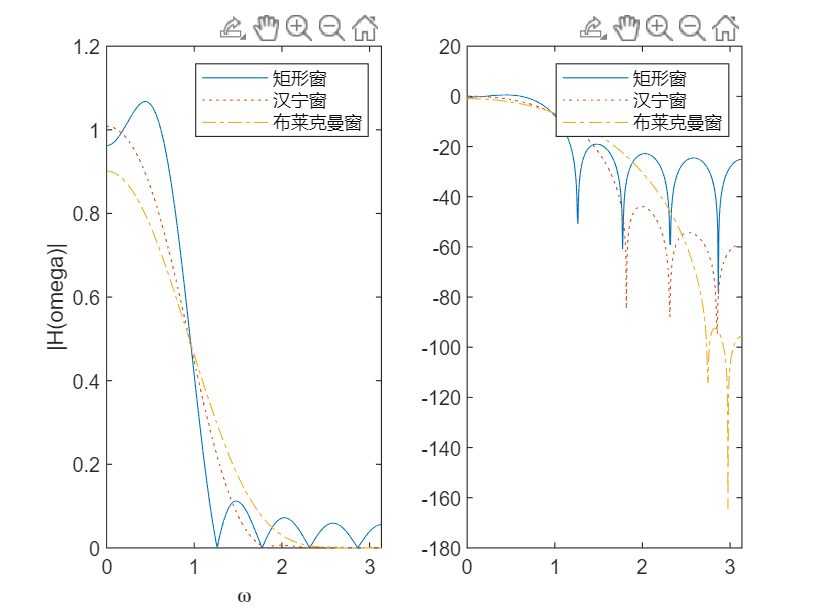

wc=0.3*pi;N=11;
hd=ideallp(wc,N);
%用wc=0.3*pi的理想低通作为逼近滤波器
wd1=boxcar(N)';b1=hd.*wd1;
%用矩形窗设计：
wd2=hanning(N)';b2=hd.*wd2;
%用汉宁窗设计：
wd3=blackman(N)';b3=hd.*wd3;
%用布莱克曼窗设计：
[H1,w]=freqz(b1,1);
%用矩形窗设计的频率特性
[H2,w]=freqz(b2,1);
%用汉宁窗设计的频率特性
[H3,w]=freqz(b3,1);
%用布莱克曼窗设计的频率特性
subplot(1,2,1),plot(w,abs(H1),w,abs(H2),':',w,abs(H3),'-.');%绘幅特性
legend('矩形窗','汉宁窗','布莱克曼窗');
xlabel('\omega');ylabel('|H(omega)|');
subplot(1,2,2),
%绘分贝幅特性
plot(w,20*log10(abs(H1)),w,20*log10(abs(H2)),':',w,20*log10(abs(H3)),'-.');
legend('矩形窗','汉宁窗','布莱克曼窗');

'矩形窗','汉宁窗','布莱克曼窗'带通

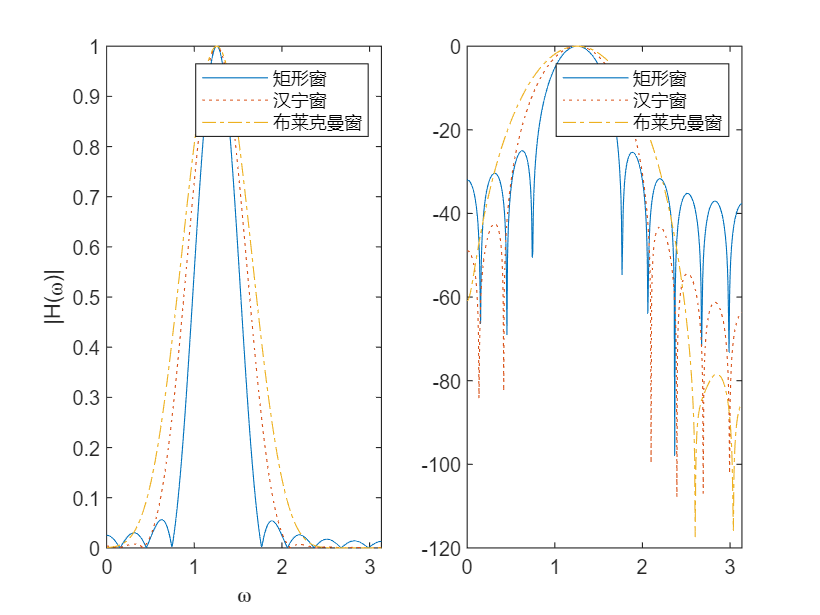

% 指定滤波器参数
delta = 0.01; % 通带和阻带最大纹波
omegap1 = 0.3*pi; % 通带截止频率1
omegap2 = 0.5*pi; % 通带截止频率2
omegas1 = 0.2*pi; % 阻带截止频率1
omegas2 = 0.6*pi; % 阻带截止频率2
Fs = 2*pi; % 采样频率

% 计算滤波器参数
Rp = -20*log10(1-delta); % 通带最大衰减（dB）
Rs = -20*log10(delta); % 阻带最小衰减（dB）
omegac = (omegap1+omegap2)/2; % 通带中心频率
domega = abs(omegap2-omegap1); % 通带带宽

% 计算滤波器长度
N = ceil((Rs-Rp)*Fs/(22*abs(domega))); % 滤波器长度
N = N + (mod(N+1,2)); % 保证滤波器为奇数阶

w1=boxcar(N);
h1 = fir1(N-1, [omegap1 omegap2]/(Fs/2), 'bandpass', w1);
%用矩形窗设计：

% 使用hanning窗设计带通滤波器
w2 = hanning(N);
h2 = fir1(N-1, [omegap1 omegap2]/(Fs/2), 'bandpass', w2);

w3=blackman(N);
%用布莱克曼窗设计：
h3 = fir1(N-1, [omegap1 omegap2]/(Fs/2), 'bandpass', w3);

% 可视化结果
[H1,w]=freqz(h1,1);
[H2, w] = freqz(h2, 1);
[H3,w]=freqz(h3,1);
subplot(1,2,1),plot(w,abs(H1),w,abs(H2),':',w,abs(H3),'-.');%绘幅特性
legend('矩形窗','汉宁窗','布莱克曼窗');
xlabel('\omega');ylabel('|H(\omega)|');
subplot(1,2,2),
%绘分贝幅特性
plot(w,20*log10(abs(H1)),w,20*log10(abs(H2)),':',w,20*log10(abs(H3)),'-.');
legend('矩形窗','汉宁窗','布莱克曼窗');

clf
x=0:0.001:0.3;
f1=10;
f2=100;
y1=sin(2*pi*f1*x);
y2=sin(2*pi*f2*x);
plot (x,y1,x,y2);
y3=y1+y2;
plot(x,y3);
signal=filter(bz1,az1,y3);
t=(0:length(x)-1)/Fs;
plot(t,signal);

function hd=ideallp(wc,N)
tao=(N-1)/2;
n=0:(N-1);
m=n-tao+eps;
hd=sin(wc*m)./(pi*m);
end